% MATLAB script to demonstrate the Fast Folding Algorithm (FFA)
% This models the logic inside your ffa_engine.v module.

clear; clc; close all;

%% 1. Setup and Parameters
fprintf('Setting up simulation parameters...\n');

Setting up simulation parameters...


fs = 50e6;                  % Clock frequency in Hz (50 MHz)
dt = 1/fs;                  % Time step in seconds

% Parameters matching your Verilog testbench
pulsar_period_s   = 1.590e-3; % True period of the simulated pulsar (1590 us)
pulse_width_s     = 0.05e-3;  % Width of the pulse (50 us)
data_buffer_size  = 16384;    % Number of samples to process
profile_bins      = 256;      % Number of phase bins in the folded profile

% Create a time vector for our data buffer
time_vector = (0:data_buffer_size-1) * dt;

%% 2. Generate a Realistic Noisy Signal
fprintf('Generating a noisy pulsar signal...\n');

Generating a noisy pulsar signal...


noise_amplitude = 2.5;
pulse_amplitude = 1.5;

% Create a baseline of random noise
noise = noise_amplitude * randn(1, data_buffer_size);

% Create a periodic pulse train using the modulo function
pulse_signal = (mod(time_vector, pulsar_period_s) < pulse_width_s) * pulse_amplitude;

% Combine them to create the final signal
input_signal = noise + pulse_signal;

%% 3. The Core FFA: Folding and Accumulation
fprintf('Starting the Fast Folding Algorithm...\n');

Starting the Fast Folding Algorithm...



% Define the range of trial periods to search around the true period
trial_periods_s = linspace(1.58e-3, 1.60e-3, 200); % Search 200 periods
trial_periods_samples = round(trial_periods_s / dt);

% Initialize a matrix to store all the folded profiles
folded_profiles = zeros(length(trial_periods_samples), profile_bins);

% Main FFA loop
for p_idx = 1:length(trial_periods_samples)
    current_trial_period = trial_periods_samples(p_idx);
    
    for n = 1:data_buffer_size
        % Calculate which phase bin this sample belongs to
        phase = mod(n - 1, current_trial_period);
        bin_index = floor((phase / current_trial_period) * profile_bins) + 1;
        
        % Add the sample's value to that bin (accumulation)
        folded_profiles(p_idx, bin_index) = folded_profiles(p_idx, bin_index) + input_signal(n);
    end
end

%% 4. Peak Detection: Find the Best Period
fprintf('Finding the period with the strongest signal...\n');

Finding the period with the strongest signal...



% Find the profile with the highest peak value
[~, best_period_idx] = max(max(folded_profiles, [], 2));
detected_period_samples = trial_periods_samples(best_period_idx);
detected_period_us = (detected_period_samples * dt) * 1e6;

fprintf('--> True Period: %.1f us\n', pulsar_period_s * 1e6);

--> True Period: 1590.0 us


fprintf('--> Detected Period: %.1f us\n', detected_period_us);

--> Detected Period: 1582.8 us


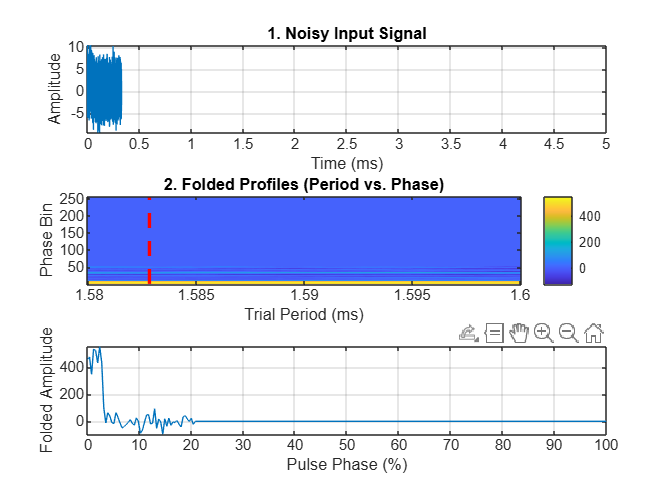


%% 5. Visualization
figure('Name', 'FFA Signal Processing Stages', 'NumberTitle', 'off');

% Plot 1: The initial noisy signal
subplot(3, 1, 1);
plot(time_vector * 1e3, input_signal);
title('1. Noisy Input Signal');
xlabel('Time (ms)');
ylabel('Amplitude');
grid on;
xlim([0 5]); % Show first 5 ms for clarity

% Plot 2: The "Periodogram" showing all folded results
subplot(3, 1, 2);
imagesc(trial_periods_s * 1e3, 1:profile_bins, folded_profiles');
title('2. Folded Profiles (Period vs. Phase)');
xlabel('Trial Period (ms)');
ylabel('Phase Bin');
set(gca,'YDir','normal');
colorbar;

hold on;
% Draw a line indicating the detected period
plot([detected_period_us/1000, detected_period_us/1000], [1, profile_bins], 'r--', 'LineWidth', 2);
hold off;

% Plot 3: The final, clean pulse profile
subplot(3, 1, 3);
best_profile = folded_profiles(best_period_idx, :);
plot(linspace(0, 100, profile_bins), best_profile);
title(sprintf('3. Detected Pulsar Profile at %.1f us', detected_period_us));
xlabel('Pulse Phase (%)');
ylabel('Folded Amplitude');
grid on;